Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Education pays off (Section 7.2)

Volker Ziemann, 211115, CC-BY-SA-4.0

In Section 7.2 we illustrate regression methods by analysing data (for 2018) from the US bureau of labor statistics. On the website [https://www.bls.gov/emp/tables/unemployment-earnings-education.htm](https://www.bls.gov/emp/tables/unemployment-earnings-education.htm) tabular data are available that link the educational attainment, which I convert to years of education past the age of 15, to the average unemployment rate and median weekly wages. The follwing table is a result of that preprocessing stage. 

%   t,  u,   w
a=[14, 1.5, 1884;   % Professional
   12, 1.6, 1825;   % Doctoral degree
    8, 2.1, 1434;   % Master
    6, 2.2, 1198;   % Bachelor
    4, 2.8,  862;   % Associate
    3, 3.7,  802;   % some college, no degree
    2, 4.1,  730;   % High-school diploma
    1, 5.6,  553];  % less than high-school diploma 

Now we give the columns in the table short names:` t` for the years of education past the age of 15, `u` for the unemplyment rate, and `w` for the weekly wages.

t=a(:,1); u=a(:,2); w=a(:,3);

First inspecting the data we observe that the points very closely follwo a straight line and we therefore fit a first order polynomial with polyfit() and plot both the original data and the regression line on the same plot. From the first coefficient of the fitted polynomial we see that we can expect an average increase in the weekly wages by 106 $ for every year of additional education.  Education pays off at this rate!

p=polyfit(t,w,1)

p =   106.3683  496.1984


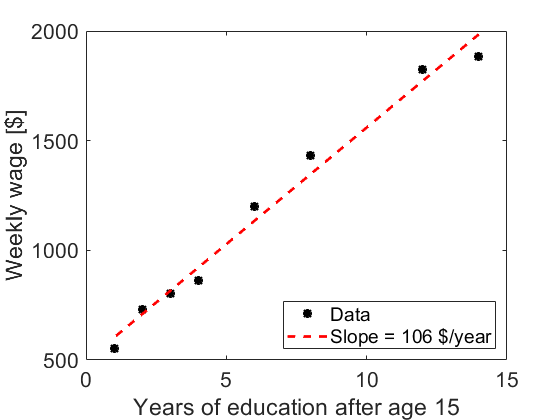

y=polyval(p,t);
plot(t,w,'k*',t,y,'r--','LineWidth',2)
xlabel('Years of education after age 15')
ylabel('Weekly wage [$]')
legend('Data','Slope = 106 $/year','Location','SouthEast')
set(gca,'FontSize',16)

let's see whether information also prevents uneployment. First plotting the data it looks more like a hyperbola than a straight line. We therefore plot (not shown)` log(t) `versus `log(u)`, which approximately shows a linear dependence and we immediately use polyfit() to find the regression coefficents, which show that the unemplyment approximately follows a $1/\sqrt{t}$ dependence. 

p=polyfit(log(t),log(u),1)

p =    -0.5123    1.7642


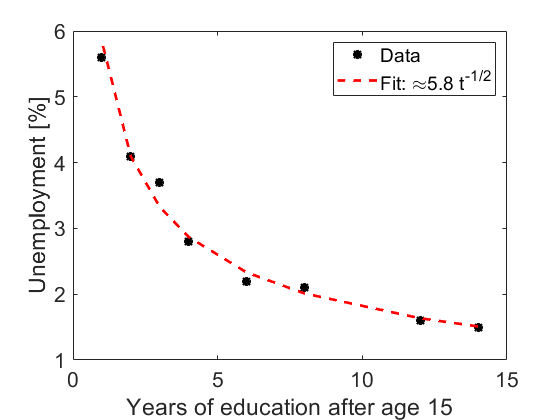

y=exp(p(2))*t.^p(1);
figure; plot(t,u,'k*',t,y,'r--','LineWidth',2)
xlabel('Years of education after age 15')
ylabel('Unemployment [%]')
legend('Data','Fit: \approx5.8 t^{-1/2}')
set(gca,'FontSize',16)

It appears that a higher education also provides some protection agains unemplyment.